mu0 = [0,0];
mu1 = [2,0];
Sigma = eye(2);
M = 100;

fld = prtClassFld+prtDecisionBinaryMinPe;

nCounts = 10;
nReps = 1000;
obsCounts = round(logspace(0,log10(40),nCounts));
legendEntries = cell(nCounts,1);
pc = nan(nCounts,nReps);
for iCount = 1:nCounts
    N = obsCounts(iCount);
    for iRep = 1:nReps
        ds_train = prtDataGenUnimodal(N,mu0,mu1,Sigma,Sigma);
        ds_test = prtDataGenUnimodal(M,mu0,mu1,Sigma,Sigma);

        fld_trained = fld.train(ds_train);
        pc(iCount,iRep) = prtScorePercentCorrect(fld_trained.run(ds_test));
    end
end

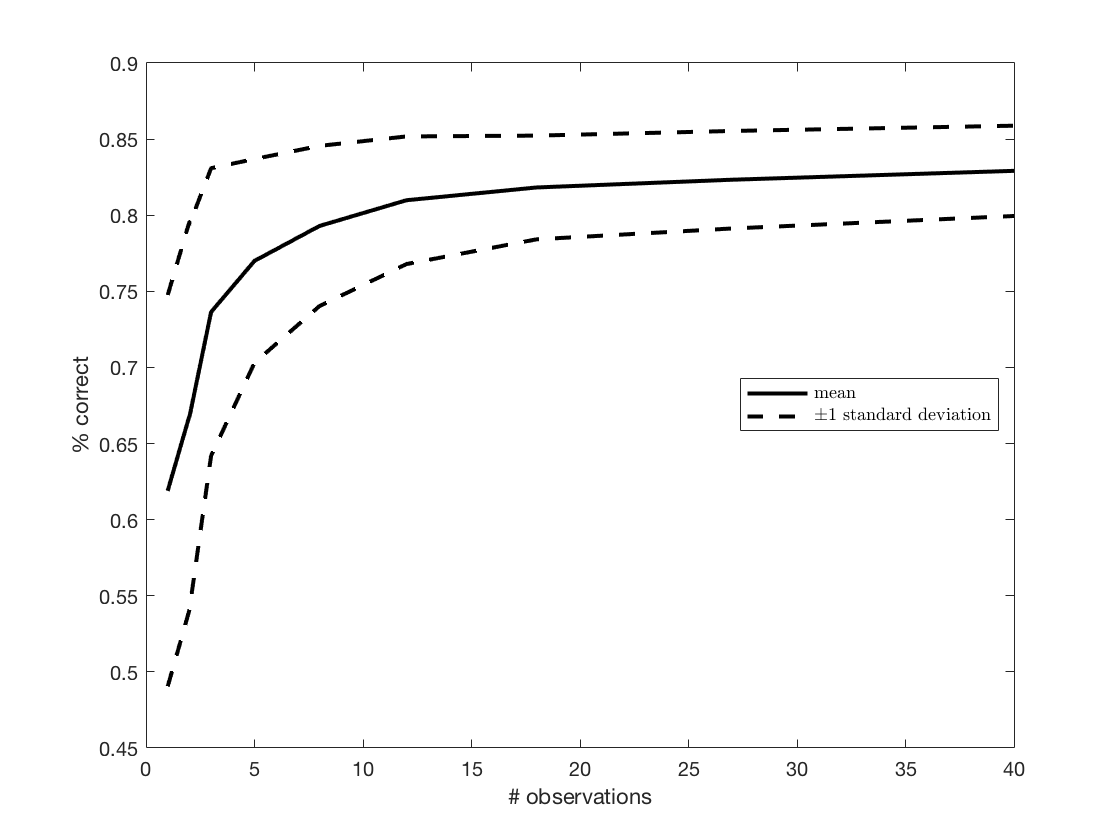

plot(obsCounts,mean(pc,2),'-',...
    obsCounts,mean(pc,2)-std(pc,0,2),'--',...
    obsCounts,mean(pc,2)+std(pc,0,2),'--',...
    'Color',[0,0,0])
xlabel('# observations')
ylabel('% correct')
l = legend('mean','$\pm$1 standard deviation',...
    'Location','best');
l.Interpreter = 'latex';